Norms for matrix

clear norm
A=rand(3);

disp([norm(A) max(sqrt(eig(A'*A)))]) %Euclidean norm

    1.4512    1.4512




disp([norm(A,inf) max(sum(abs(A),2)) ]) %Uniform norm

    1.6895    1.6895




disp([norm(A,1)  max(sum(abs(A)))]) %Taxicab norm

    1.5771    1.5771



Visualize matrix norm on compass

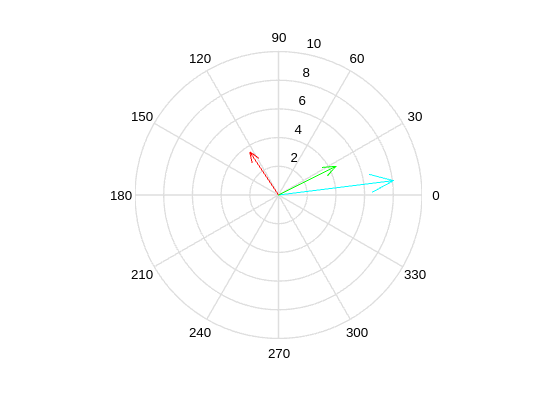

A=2*eye(2);
B=diag([4 1]);
C=[-2 2; 1 1];
v=[2 1]';
vA=A*v;
vB=B*v;
vC=C*v;

compass(vB(1),vB(2),'c'); hold on
compass(vA(1),vA(2),'g');
compass(vC(1),vC(2),'r');

disp(norm(v));

    2.2361



disp([norm(A) norm(B) norm(C); norm(vA) norm(vB) norm(vC) ]);

    2.0000    4.0000    2.8284
    4.4721    8.0623    3.6056



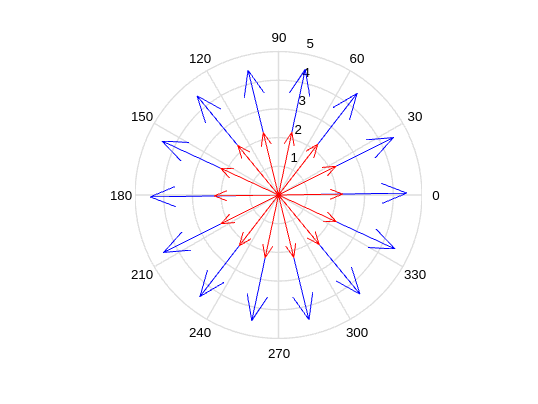


%-----------------------------------------
%Same example but with Complex Vectors
clf;
N=15;
t=linspace(-pi,pi,N); z=(2+i)*exp(i*t);
v=[real(z);imag(z)]; vA=A*v; vB=B*v; vC=C*v;

figure; compass(vA(1,:),vA(2,:),'b'); hold on; compass(z,'r')

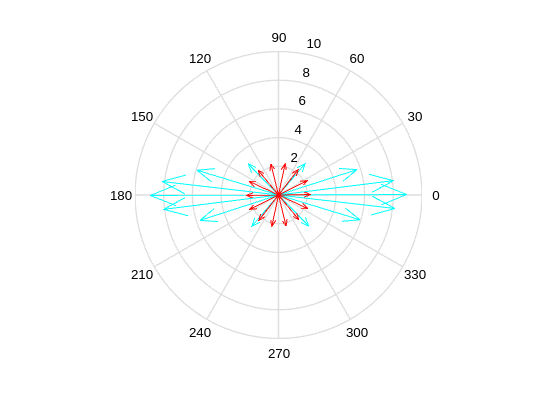

figure; compass(vB(1,:),vB(2,:),'c'); hold on; compass(z,'r')

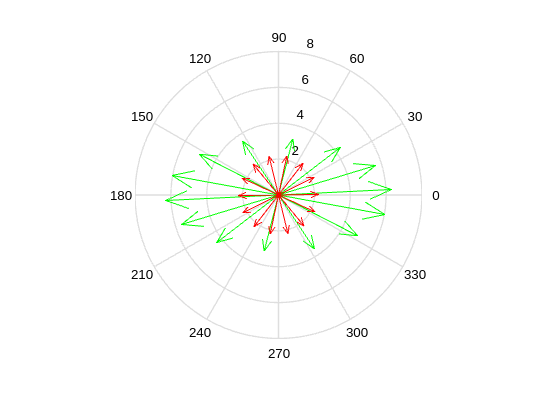

figure; compass(vC(1,:),vC(2,:),'g'); hold on; compass(z,'r')

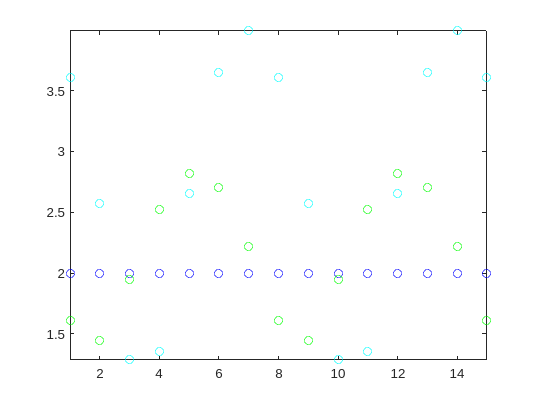

clf;

%Now compute the norm for each column in the matrix
nv=vecnorm(v);
nvA=vecnorm(vA);
nvB=vecnorm(vB);
nvC=vecnorm(vC);
figure;
h=plot((1:N), [(nvA./nv)' (nvB./nv)' (nvC./nv)'],'o');
set(h(1),'Color','b'); set(h(2),'Color','c'); set(h(3),'Color','g');
axis tight;

% with pointers because we're using complex numbers.

Lab: estimate $||A||$ using the Symbolic Math Toolbox

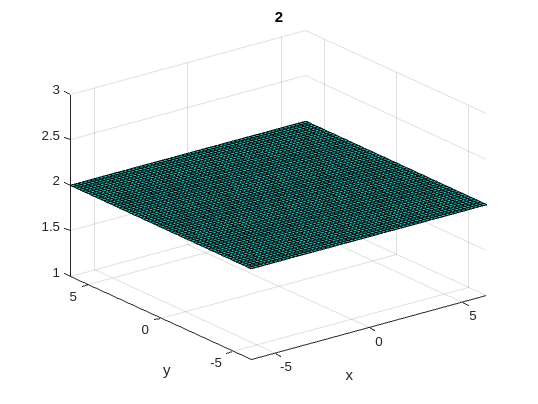

clf;
A=2*eye(2); B=diag([4 1]); C=[-2 2; 1 1];
syms x y real; v=[x y]';
Anorm=simplify(norm(A*v)/norm(v)); ezsurf(Anorm);
Bnorm=simplify(norm(B*v)/norm(v)); ezsurf(Bnorm);

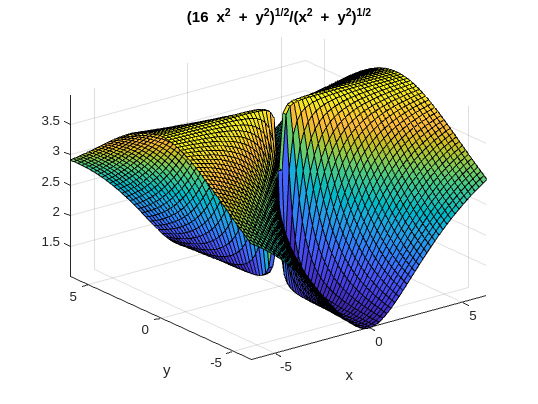

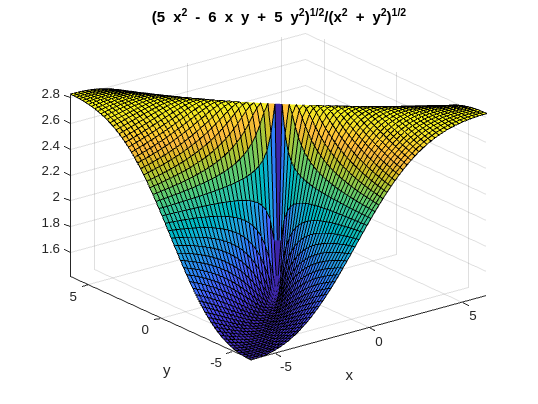

Cnorm=simplify(norm(C*v)/norm(v)); ezsurf(Cnorm);

disp([ norm(A) norm(B) norm(C) ])

    2.0000    4.0000    2.8284



%--------------------------------
AX=axis;
disp(AX(5:6))

    1.4142    2.8284



disp(zlim)

    1.4142    2.8284



Lab: estimate $||B||$

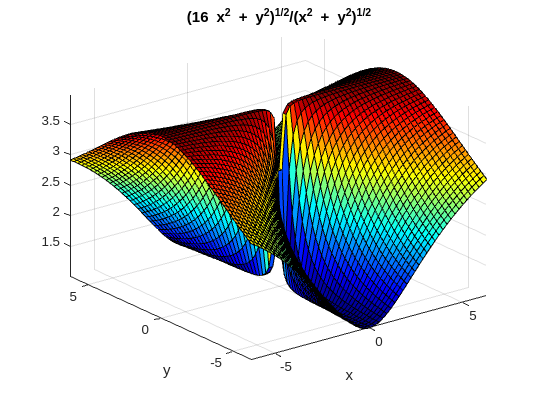

clf;
B=diag([4 1]);
Bnorm=simplify(norm(B*v)/norm(v)); ezsurf(Bnorm); colormap('jet');

G=simplify(gradient(Bnorm)); %Calculate B gradient
disp(G)

$$\left(\begin{array}{c} \frac{15\,x\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{3/2}\,\sqrt{16\,x^{2}+y^{2}}}\\ -\frac{15\,x^{2}\,y}{{\left(x^{2}+y^{2}\right)}^{3/2}\,\sqrt{16\,x^{2}+y^{2}}} \end{array}\right)$$

%Search for stationary points (punti critici)
S=solve(G(1)==0,G(2)==0, 'ReturnConditions',true)

S = struct with fields:
             x: [2×1 sym]
             y: [2×1 sym]
    parameters: u
    conditions: [2×1 sym]


[S.x(1);S.y(1)] % x axis

$$ans = \left(\begin{array}{c} u\\ 0 \end{array}\right)$$

[S.x(2);S.y(2)] % y axis

$$ans = \left(\begin{array}{c} 0\\ u \end{array}\right)$$

V1=simplify(subs(Bnorm, {x y},{S.x(1),S.y(1)}))

$$V1 = 4$$

V2=simplify(subs(Bnorm, {x y},{S.x(2),S.y(2)})) 

$$V2 = 1$$

%with the X-Z view we see that the surface is all between 1 and 4

%Experiment: can we use the Hessina matrix H to locate the local extrema?
H=hessian(Bnorm, [x,y]);
detH=det(H);
disp(subs(detH,{x,y},{S.x(1),S.y(1)})) %det(H)=0, so nothing can be said.

$$0$$


clf;

Let's now highlight where $||\nabla \phi(x_1^*,x_2^*)||_2=0$

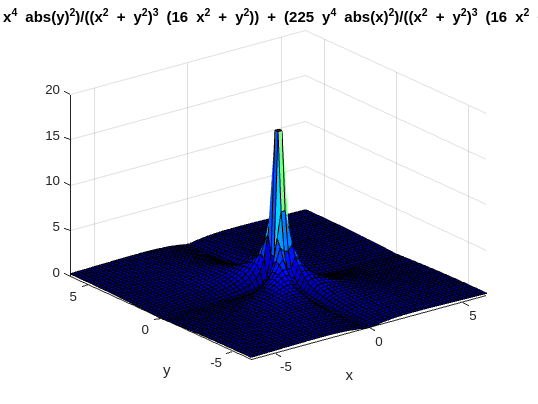

G=simplify(gradient(Bnorm)); ezsurf(norm(G));

%In this case, the surface is not negative and it may preferable to draw
%the log10
clf;
ezsurf(log10(norm(G))); %now it is clear where the minimum are. 
%Trying a X-Y view, we see that in the axis (x,y) of the function there are
%minimum, and in the (0,0) there is a maximum

Estimate $||C||$

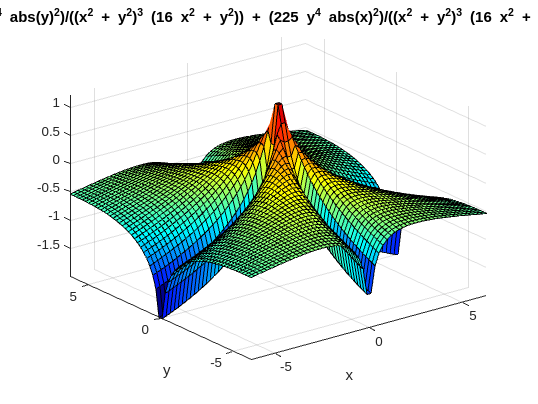

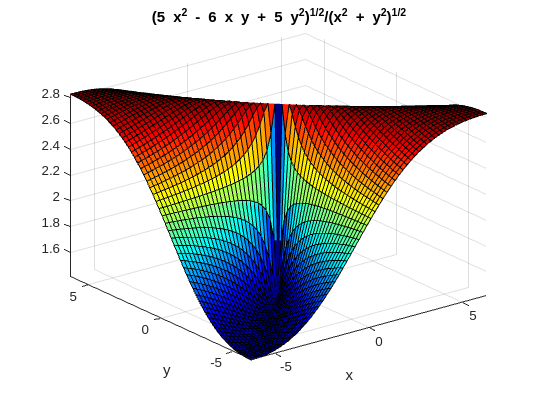

C=[-2 2; 1 1]; syms x y real; v=[x y]';
Cnorm=simplify(norm(C*v)/norm(v));
ezsurf(Cnorm); colormap('jet');

G=simplify(gradient(Cnorm));
S=solve(G(1)==0, G(2)==0, 'ReturnConditions',true);
S.parameters;
S.conditions;
S.x

$$ans = \left(\begin{array}{c} -u\\ u \end{array}\right)$$

S.y

$$ans = \left(\begin{array}{c} u\\ u \end{array}\right)$$

V1=simplify(subs(Cnorm, {x y},{S.x(1),S.y(1)})) %max

$$V1 = 2\,\sqrt{2}$$

V2=simplify(subs(Cnorm, {x y},{S.x(2),S.y(2)})) %min

$$V2 = \sqrt{2}$$


%Try to calc the hessian
detH=det(hessian(Cnorm,[x y]));
disp(subs(detH, {x,y},{S.x(1),S.y(1)}))

$$0$$


%Now let's highligh where the gradient is zero
G=simplify(gradient(Cnorm));
Gnorm=simplify(norm(G));
clf;
fsurf(log10(Gnorm)); box on; axis equal;

Estimate the condition number of A

clear norm min max;
A=2*eye(2); syms x y real; v=[x y]';
disp(A);

     2     0
     0     2



Avnorm=norm(A*v)

$$Avnorm = \sqrt{4\,{\left|x\right|}^{2}+4\,{\left|y\right|}^{2}}$$

vnorm=norm(v)

$$vnorm = \sqrt{{\left|x\right|}^{2}+{\left|y\right|}^{2}}$$

Anorm=simplify(norm(A*v)/norm(v));
disp(Anorm);

$$2$$


%G=simplify(gradient(Anorm)) %Gradient is null

%cond(A);

B=diag([4 1]);
%Bnorm=simplify(norm(B*v)/norm(v)); disp(Bnorm);
%G=simplify(gradient(Bnorm))
%S=solve(simplify(gradient(Bnorm))==0,'ReturnConditions',true)

%min=subs(Bnorm,{x,y},{S.x(1),S.y(2)})
%max=subs(Bnorm,{x,y},{S.x(2),S.y(2)})
%k=max/min


eigA=eig(A)

eigA =      2
     2


eigAt=eig(A')

eigAt =      2
     2


eigAxAt=eig(A'*A)

eigAxAt =      4
     4


sq_eigAxAt=sqrt(eigAxAt)

sq_eigAxAt =      2
     2


maxx=max(sqrt(eig(A'*A)))

maxx = 2

minn=min(sqrt(eig(A'*A)))

minn = 2

k=maxx/minn

k = 1

condA=cond(A)

condA = 1


eigB=eig(B'*B);
normB=sqrt(eigB)

normB =      1
     4


normB_matlab=norm(B)

normB_matlab = 4


k=max(normB)/min(normB)

k = 4

condB=cond(B)

condB = 4


C=[-2 2; 1 1]

C =     -2     2
     1     1


eigC_Ct=eig(C'*C)

eigC_Ct =      2
     8


s=sqrt(eig(C'*C))

s =     1.4142
    2.8284



k=max(s)/min(s) cond(C)

k = 2

ans = 2.0000